# Identificazione dei parametri dinamici - calcolo dei parametri dinamici da una traiettoria

Carico Pinocchio

clear all;
close all;
clc;
pin=py.importlib.import_module('pinocchio');
numpy=py.importlib.import_module('numpy');
model_name="scara0";
model = py.pinocchio.buildModelFromUrdf(model_name+"/model.urdf");
model_data = model.createData();
dof=double(model.nq);

carico la matrice di cambio variabili $T$ e il rango $b$

load(model_name+"/regressorT.mat");

carico la traiettoria

trajectory_name="random_trj_20250221160021";
load(model_name+"\tests\"+trajectory_name+".mat")
if isrow(time) % ensure the time is a column
    time=time';
end

Visto che i dati sono rumorosi e devo calcolare le accelerazioni utilizzo un filtro di Savitzky-Golay, è importante filtrate tutti i dati nello stesso modo per evitare lag temporali fra ingresso e uscita.

window_size = 31; % Must be odd
poly_order = 3;   % Polynomial order
[~,g] = sgolay(poly_order,window_size);
dt=time(2)-time(1);

Filtro i dati

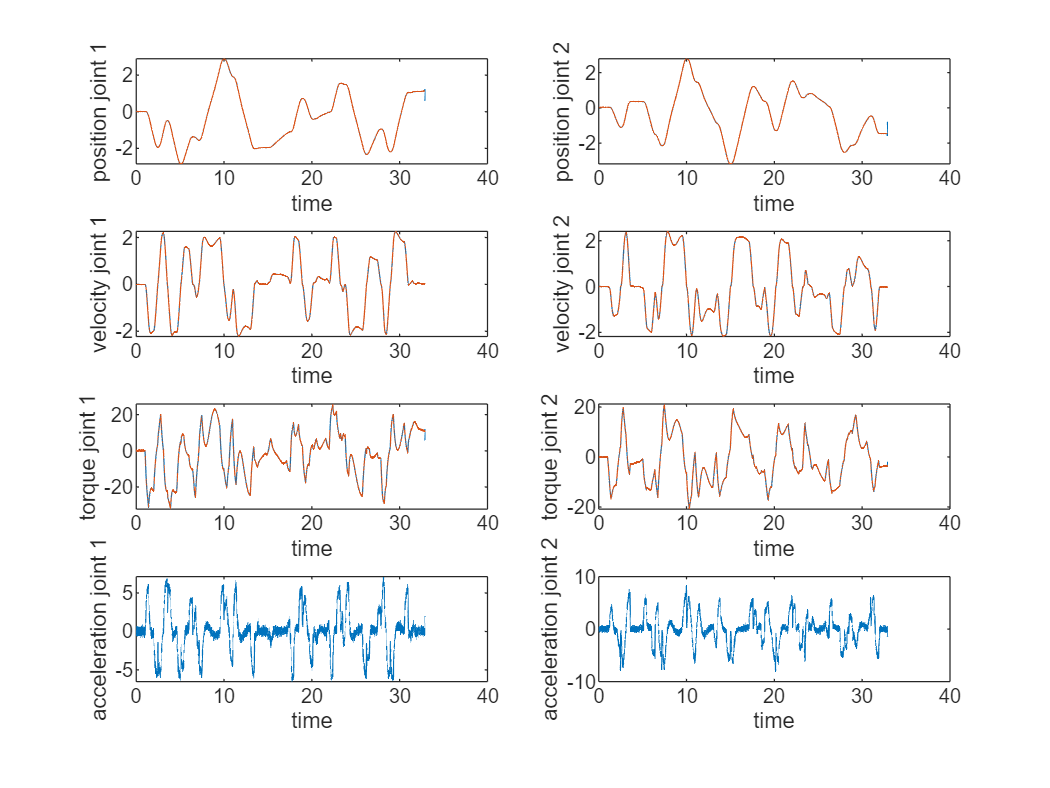

figure(1)
for idof=1:dof
    joint_position_filtered(:,idof) = conv(joint_position(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_velocity_filtered(:,idof) = conv(joint_velocity(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_torque_filtered(:,idof) = conv(joint_torque(:,idof), g(:,1), 'same'); % Smoothing using SG filter
    joint_acceleration_filtered(:,idof) = conv(joint_velocity(:,idof), g(:,2), 'same') / dt; % First derivative using SG filter

    subplot(4,dof,idof)
    plot(time,joint_position_filtered(:,idof),time,joint_position(:,idof))
    xlabel('time')
    ylabel(sprintf('position joint %d',idof))

    subplot(4,dof,idof+dof)
    plot(time,joint_velocity_filtered(:,idof),time,joint_velocity(:,idof))
    xlabel('time')
    ylabel(sprintf('velocity joint %d',idof))

    subplot(4,dof,idof+2*dof)
    plot(time,joint_torque_filtered(:,idof),time,joint_torque(:,idof))
    xlabel('time')
    ylabel(sprintf('torque joint %d',idof))


    subplot(4,dof,idof+3*dof)
    plot(time,joint_acceleration_filtered(:,idof))
    xlabel('time')
    ylabel(sprintf('acceleration joint %d',idof))


end

Calcolo il regressore sui dati sperimentali, scarto i primi secondi, prendo un dato ogni 10 per velocizzare l'algoritmo

A=[];
Y=[];
for idx=1000:10:size(joint_position,1)-1000
    q_numpy=py.numpy.array(joint_position_filtered(idx,:));
    v=joint_velocity_filtered(idx,:);
    v_numpy=py.numpy.array(v);
    a_numpy=py.numpy.array(joint_acceleration_filtered(idx,:));
    Phi_dynamic=double(py.pinocchio.computeJointTorqueRegressor(model,model_data,q_numpy,v_numpy,a_numpy));
    Phi_friction=[diag(v) diag(tanh(100*v))];
    Phi=[Phi_dynamic,Phi_friction];

    A=[A;Phi];

    tau=joint_torque_filtered(idx,:)';
    Y=[Y;tau];
end

Ottenuto il regressore, calcolo il regressore di base, dove $A_{tmp}=\left[
\begin{array}{cc}
A_b & \mathbf{0}
\end{array}
\right]=AT^{-1}=AT^{T}$

Atmp=A*T';
Ab=Atmp(:,1:b);

calcolo parametri base

pb=Ab\Y;

scelgo i parametri del nullo pari a zero.

pnull=zeros(size(A,2)-b,1);

calcolo i parametri dinamici

p=T'*[pb;pnull];

calcolo Y del modello

Ymodel=A*p;

Separo le predizioni per i singoli giunti

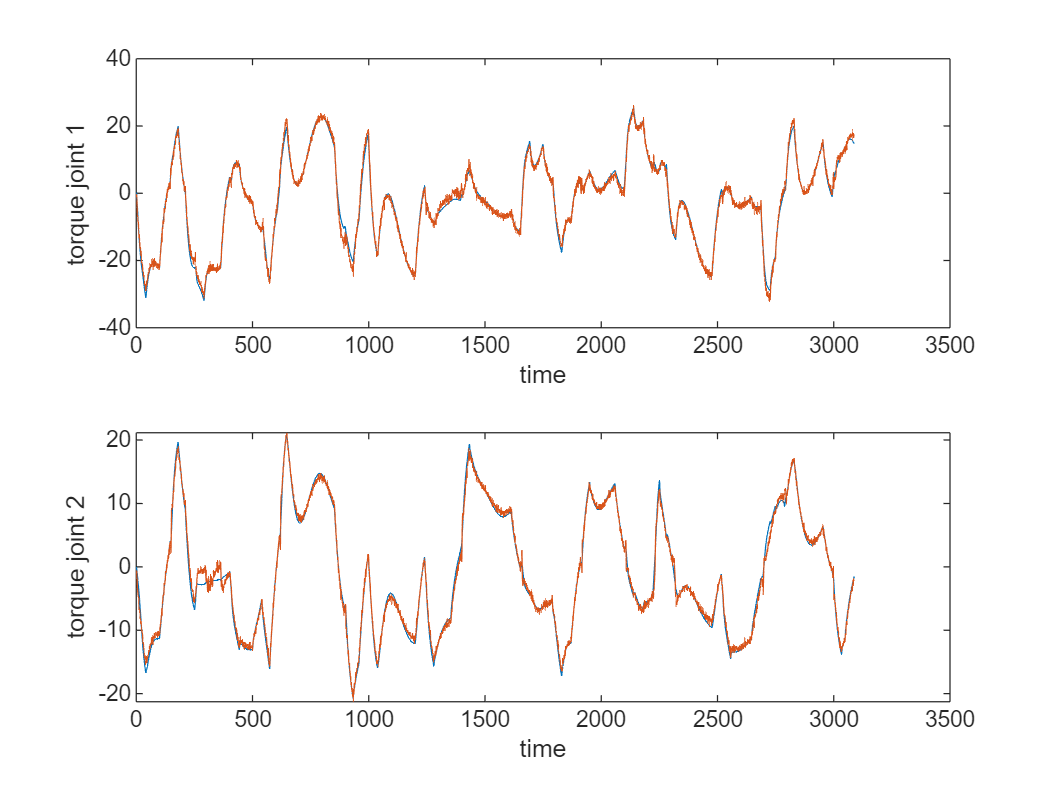

ymodel=reshape(Ymodel,dof,[])';
y=reshape(Y,dof,[])';

figure(2)
for idof=1:dof

    subplot(dof,1,idof)
    plot([y(:,idof),ymodel(:,idof)])
    xlabel('time')
    ylabel(sprintf('torque joint %d',idof))
end

Stampo i parametri in formato yaml

fprintf('model_parameters:\n');

model_parameters:


for ip=1:length(p)
    fprintf('- %f\n',p(ip));
end

- 0.000000
- 0.972830
- -0.023873
- 0.000000
- -0.000000
- 0.000000
- -0.000000
- 0.000000
- 0.000000
- -1.635114
- 0.127514
- 0.245142
- -0.010845
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- 0.000000
- -0.945401
- 3.207053
- 3.242633
- 4.588067
- 4.549484
